Process Sensor Streams 

% Load rosbag data 
bagSelect = rosbag('2022-08-02-00-27-09.bag');

% Capture data on /zlac8015d/encoder topic 
encoderLog = select(bagSelect, 'Topic','/zlac8015d/encoder');

% Capture data on /amr/status/ 
voltageLog = select(bagSelect, 'Topic', '/amr/status/voltage');
currentLog = select(bagSelect, 'Topic', '/amr/status/current'); 

% Read data 
encoderPlot = readMessages(encoderLog);
voltagePlot = readMessages(voltageLog);
currentPlot = readMessages(currentLog); 

% Determine vector length
[encoderLength,~] = size(encoderPlot);
[voltageLength,~] = size(voltagePlot); 
[currentLength,~] = size(currentPlot); 

% Preallocate array sizes
leftEncoder = zeros(encoderLength,1);
rightEncoder = zeros(encoderLength,1);
leftRPM = zeros(encoderLength,1);
rightRPM = zeros(encoderLength,1); 
voltage = zeros(voltageLength, 1); 
current = zeros(currentLength, 1); 

% Parse encoder data 
for i = 1:encoderLength
    leftEncoder(i,1) = encoderPlot{i}.Data(1,:);
    rightEncoder(i,1) = -encoderPlot{i}.Data(2,:);
    leftRPM(i,1) = encoderPlot{i}.Data(3,1); 
    rightRPM(i,1) = encoderPlot{i}.Data(4,1); 
end 

% Parse voltage data
for i = 1:voltageLength
    voltage(i,1) = voltagePlot{i}.Data(1,:); 
end

% Parse current data
for i = 1:currentLength
    current(i,1) = currentPlot{i}.Data(1,:);
end

% Voltage time parsing
voltageTimeLog = voltageLog.MessageList.Time; 
voltageTime = zeros(length(voltageTimeLog), 1); 

% Current time parsing
currentTimeLog = currentLog.MessageList.Time; 
currentTime = zeros(length(currentTimeLog), 1); 

% Encoder time parsing
encoderTimeLog = encoderLog.MessageList.Time; 
encoderTime = zeros(length(encoderTimeLog), 1); 
encoderTimeStep = zeros(length(encoderTimeLog), 1);

% Calculate encoder time 
for i = 1:(length(encoderTimeLog))
    encoderTime(i,1) = (encoderTimeLog(i) -  encoderTimeLog(1));
end

% Calculate encoder time step 
for i = 1:(length(encoderTime) - 1)
    encoderTimeStep(i,1) = encoderTime(i+1,1) - encoderTime(i,1);  
end

% Calculate voltage time
for i = 1:(length(voltageTimeLog))
    voltageTime(i,1) = (voltageTimeLog(i) - voltageTimeLog(1));
end

% Calculate current time
for i = 1:(length(currentTimeLog))
    currentTime(i,1) = (currentTimeLog(i) - currentTimeLog(1));
end

Process Pose Calculations

load('poses.mat'); 

slamCorrectedPose = zeros(length(out.slamPose.Data(:,1)), 2);

% Translate SLAM pose
for i = 1:length(slamCorrectedPose)
   temp = transpose([out.slamPose.Data(i,1); out.slamPose.Data(i,2)]); 
   temp = temp + [0.320706, 0.007];
   slamCorrectedPose = [slamCorrectedPose; temp];
end

truth = sortrows(readmatrix('truth.txt')); 

Plot voltage calculation

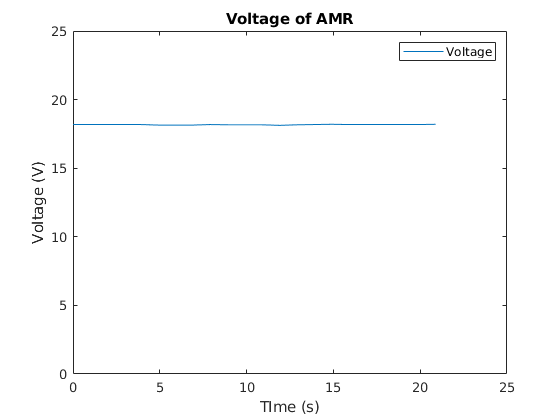

plot(voltageTime, voltage); 
title('Voltage of AMR'); 
ylabel('Voltage (V)'); 
xlabel('TIme (s)'); 
legend('Voltage'); 
ylim([0,25]); 

Plot current calculations

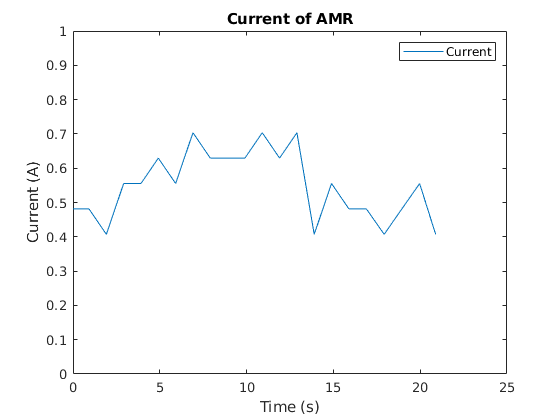

plot(currentTime, current); 
title('Current of AMR'); 
ylabel('Current (A)'); 
xlabel('Time (s)'); 
legend('Current'); 
ylim([0,1]); 

Plot Wheel Encoder Data

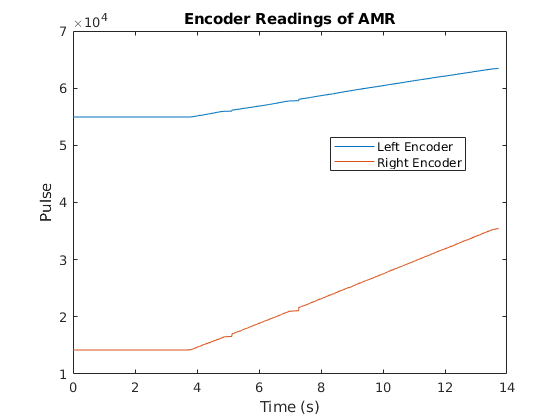

plot(encoderTime, leftEncoder);
hold on
title('Encoder Readings of AMR');
xlabel('Time (s)');
ylabel('Pulse');    
plot(encoderTime, rightEncoder);
legend('Left Encoder', 'Right Encoder', 'Location', 'best')
hold off 

Plot Calculated RPM Data 

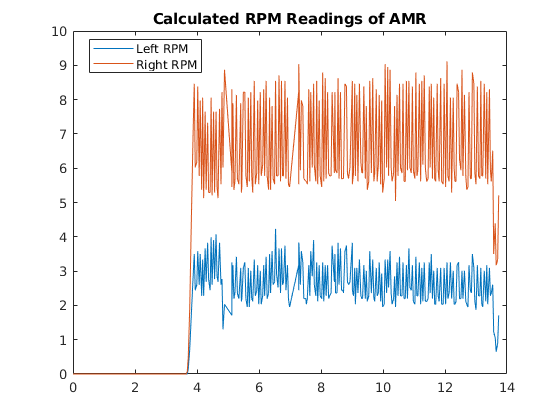

calcLeftRPM = zeros(encoderLength - 1, 1); 
calcRightRPM = zeros(encoderLength - 1, 1); 
leftFreq = zeros(encoderLength - 1, 1); 
rightFreq = zeros(encoderLength - 1, 1); 
leftEncoderChange = zeros(encoderLength - 1, 1);
rightEncoderChange = zeros(encoderLength - 1, 1);

% Calculate Frequency 
for i = 1:(encoderLength - 1)
    leftFreq(i,1) = (leftEncoder(i+1) - leftEncoder(i))/0.03;
    rightFreq(i,1) = (rightEncoder(i+1) - rightEncoder(i))/0.03;
end

% Calcualte RPM 
for i = 1:length(leftFreq)
    calcLeftRPM(i,1) = (leftFreq(i,1)*10.0)/4096.0; 
    calcRightRPM(i,1) = (rightFreq(i,1)*10.0)/4096.0; 
end

%Calcualte Encoder Change 
for i = 1:(encoderLength - 1)
    leftEncoderChange(i,1) = leftEncoder(i+1) - leftEncoder(i); 
    rightEncoderChange(i,1) = rightEncoder(i+1) - rightEncoder(i); 
end

plot(encoderTime(2:end), calcLeftRPM);
hold on 
title('Calculated RPM Readings of AMR');
plot(encoderTime(2:end), calcRightRPM); 
legend('Left RPM', 'Right RPM', 'Location', 'best')
hold off 

Plot Measured Encoder Data

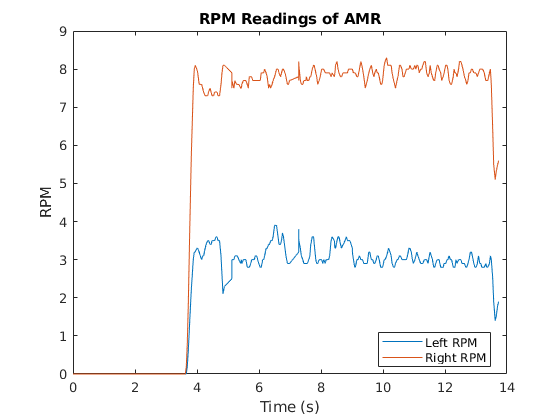

plot(encoderTime, leftRPM);
hold on
title('RPM Readings of AMR');
xlabel('Time (s)');
ylabel('RPM');
plot(encoderTime, rightRPM);
legend('Left RPM', 'Right RPM', 'Location', 'best')
hold off

Plot Estimated Encoder Poses

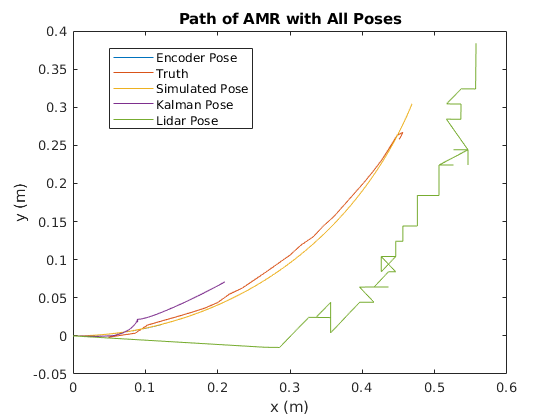

plot(out.encoderPose.Data(:,1), out.encoderPose.Data(:,2));
hold on
title('Path of AMR with All Poses');
xlabel('x (m)');
ylabel('y (m)');
plot(truth(:,2), truth(:,3));
plot(out.simulatedPose.Data(:,1), out.simulatedPose.Data(:,2));
plot(out.kfPose.Data(:,1), out.kfPose.Data(:,2));
plot(slamCorrectedPose(:,1), slamCorrectedPose(:,2));
legend('Encoder Pose', 'Truth', 'Simulated Pose', 'Kalman Pose', 'Lidar Pose', 'Location','best')
hold off 

Plot Encoder Pose with Ground Truth

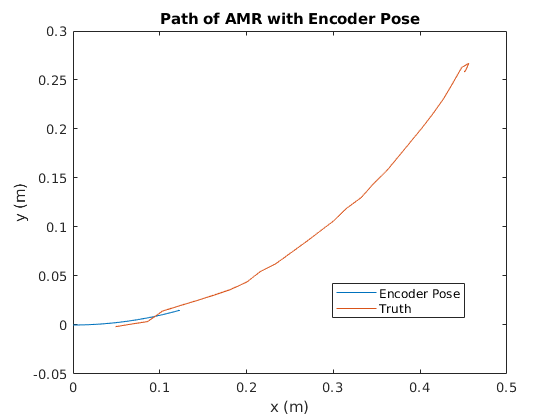

plot(out.encoderPose.Data(:,1), out.encoderPose.Data(:,2));
hold on
title('Path of AMR with Encoder Pose');
xlabel('x (m)');
ylabel('y (m)');
plot((truth(:,2)), (truth(:,3)));
legend('Encoder Pose', 'Truth', 'Location','best')
hold off 

Plot Kalman Pose with Ground Truth

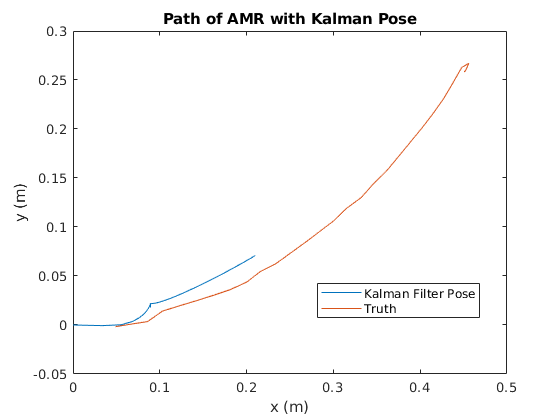

plot(out.kfPose.Data(:,1), out.kfPose.Data(:,2));
hold on
title('Path of AMR with Kalman Pose');
xlabel('x (m)');
ylabel('y (m)');
plot((truth(:,2)), (truth(:,3)));
legend('Kalman Filter Pose', 'Truth', 'Location','best')
hold off 

Plot Corrected SLAM Pose with Ground Truth 

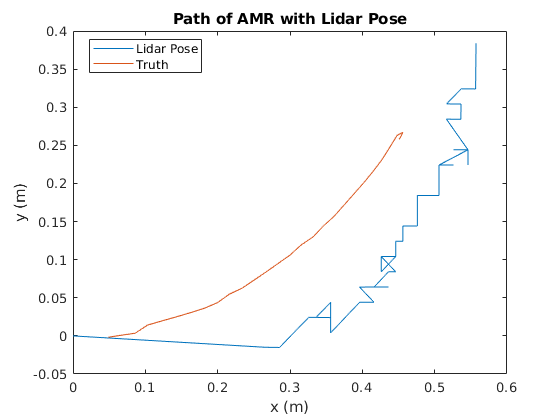

plot(slamCorrectedPose(:,1), slamCorrectedPose(:,2));
hold on
title('Path of AMR with Lidar Pose');
xlabel('x (m)');
ylabel('y (m)');
plot((truth(:,2)), (truth(:,3)));
legend('Lidar Pose', 'Truth', 'Location','best')
hold off 